# Create Path Following Model Predictive Controller

Now that you have broken a high-level planning problem into smaller problems of global path planning in a road network ([Create Route Planner for Offroad Navigation Using Digital Elevation Data](matlab:open('./CreateRoutePlannerUsingDigitalElevationData.mlx'))), terrain-aware planning to enter and exit the road network ([Create Onramp and Terrain-Aware Global Planners for Offroad Navigation](matlab:open('./CreateTerrainAwareGlobalPlanners.mlx'))), and obstacle-aware local planning ([Navigate Global Path Through Offroad Terrain Using Local Planner](matlab:open('./CreateLocalPlannerToNavigateGlobalPath.mlx'))), you can use a model predictive controller (MPC) to follow your planned paths. In this example, you adapt the [`nlmpcMultistage`](https://www.mathworks.com/help/mpc/ref/nlmpcmultistage.html) object for offroad driving. MPCs use a model of vehicle kinematics to predict vehicle movements and optimize control inputs like steering, throttle, and braking to achieve outcomes, such as following a path more closely or ensuring smoother driving. The MPC predicts and optimizes by minimizing a cost function, which quantifies how far the current strategy is from the desired outcome, to meet specific goals or criteria. Unlike a simpler control method like PID, which maintains consistent performance without real time adjustments, an an MPC looks ahead to plan the best moves in advance, and adjusts its strategies in real time also adjusts its strategies in real-time, ensuring the vehicle responds optimally over a defined timeline. For more information about MPC control, see [What Is Model Predictive Control](https://www.mathworks.com/help/mpc/gs/what-is-mpc.html). 

## Create Multistage Nonlinear MPC

Traditional MPCs assume a linear system, in which any change to an input like steering or acceleration leads to a proportional change in outputs such as vehicle direction or speed. However in vehicle dynamics, this relationship is not linear. Changes in inputs can have complex effects on outputs due to factors like friction, aerodynamics, and the mechanical properties of the vehicle. Therefore, for this offroad navigation application, you must implement a multistage nonlinear MPC. A multistage nonlinear MPC can understand and manage the relationship between control inputs and their outputs in a nonlinear system like a vehicle. For more information about multistage nonlinear MPCs, see [Nonlinear MPC](https://www.mathworks.com/help/mpc/ug/nonlinear-mpc.html).

Set the parameters for the multistage nonlinear MPC such that it runs at 10 Hertz, with a prediction horizon of 1 second, enabling 10 control stages for the controller.

tsMPC = 0.1;
mpcHorizon = 1;
nStage = mpcHorizon/tsMPC;

The [`nlmpcMultistage`](https://www.mathworks.com/help/mpc/ref/nlmpcmultistage.html) object enables you to generalize it to any plant and control model. Because the vehicle in this example is a three degree-of-freedom (DOF) wheeled vehicle, you can represent the system using a bicycle model. The state of the vehicle is $\left\lbrack x\;y\;\theta \;\right\rbrack$, and the vehicle control commands are velocity and steering angle $\left\lbrack v\;\alpha \;\right\rbrack$.

Create the multistage nonlinear MPC as an `nlmpcMultistage` object with 10 control stages, 3 states, and 2 control inputs. 

mpcverbosity("off")

ans = 'on'

stateSize = 3;
controlSize = 2;
nlobjTracking = nlmpcMultistage(nStage,stateSize,controlSize);
nlobjTracking.Optimization.Solver = "fmincon";
nlobjTracking.Ts = tsMPC;

## Vehicle Parameters

To represent the vehicle, use the vehicle parameters defined for the TEB controller in the Navigate Global Path Through Offroad Terrain Using Local Planner example. Maintaining consistent values between the TEB controller and MPC ensures that paths generated by the TEB planner are feasible for the downstream MPC to follow.

Use the `exampleHelperTEBParams` helper function to define the ego vehicle parameters. The ego vehicle has two axles and four wheels. 

[tunableTEBParams,fixedTEBParams] = exampleHelperTEBParams

tunableTEBParams = struct with fields:
           LookaheadTime: 6
    ObstacleSafetyMargin: 1
             CostWeights: [1×1 struct]
        MinTurningRadius: 17.2000
             MaxVelocity: [16 0.9302]
         MaxAcceleration: [0.6000 0.1000]
      MaxReverseVelocity: 8


fixedTEBParams = struct with fields:
                Length: 6.5000
                 Width: 5.7600
          NumIteration: 3
    ReferenceDeltaTime: 0.2000
      RobotInformation: [1×1 struct]


vWheelBase = fixedTEBParams.Length;

Specify the prediction model function and its analytical Jacobian function in the controller object. Because the model requires one parameter `vWheelBase`, set `Model.ParameterLength` to 1.

nlobjTracking.Model.StateFcn = "exampleHelperBicycleDerivative_MultiStage";
nlobjTracking.Model.StateJacFcn = "exampleHelperBicycleJacobian_MultiStage";
nlobjTracking.Model.ParameterLength = 1;

The multistage nonlinear MPC MPC two variables it manipulates that represent your control variables. Each manipulated variable has two sets of limits. These limits specify the minimum and maximum allowable values and the minimum and maximum allowable rates of change for the variables. For `ManipulatedVariables(1)`, these limits are on the linear velocity and the linear acceleration of the ego vehicle. For `ManipulatedVariables(2)`, these limits are on the steering angle and the steering angle rate of change.

Set these limits for linear velocity and linear acceleration.


$$-2 \text{ m/s} \leq \text{Linear Velocity} \leq 2 \text{ m/s}$$



$$-1.4 \text{ m/s}^2 \leq \text{Linear Acceleration} \leq 3.33 \text{ m/s}^2$$


nlobjTracking.UseMVRate = true;
nlobjTracking.ManipulatedVariables(1).Min = -tunableTEBParams.MaxReverseVelocity;
nlobjTracking.ManipulatedVariables(1).Max = tunableTEBParams.MaxVelocity(1);
nlobjTracking.ManipulatedVariables(1).RateMin = -tunableTEBParams.MaxAcceleration(1);
nlobjTracking.ManipulatedVariables(1).RateMax = tunableTEBParams.MaxAcceleration(1);

Set these limits for steering angle and the steering angle rate of change.


$$-\frac{\pi}{6}\text{ rad} \leq \text{Steering Angle} \leq \frac{\pi}{6}\text{ rad}$$



$$$-0.5 \text{ rad/s} \leq \text{Steering Angle Rate of Change} \leq 0.5 \text{ rad/s} $$$


nlobjTracking.ManipulatedVariables(2).Min = -tunableTEBParams.MaxVelocity(2);
nlobjTracking.ManipulatedVariables(2).Max = tunableTEBParams.MaxVelocity(2);
nlobjTracking.ManipulatedVariables(2).RateMin = -tunableTEBParams.MaxAcceleration(2);
nlobjTracking.ManipulatedVariables(2).RateMax = tunableTEBParams.MaxAcceleration(2);

Create a straight-line reference path for the multistage nonlinear MPC to follow, using the maximum allowable linear velocity to calculate the path increments over a specified number of points, ensuring the path adheres to the velocity constraints.

vNom = nlobjTracking.ManipulatedVariables(1).Max;
ds = tsMPC*vNom;
nPt = 100;
refPath = linspace(0,ds*nPt,nPt+1)'.*[1 0 0];

Define the cost function and the gradient function using the provided helper functions: `exampleHelperBicycleCost_MultiStage` and `exampleHelperBicycleGradient_MultiStage`. 

The cost function is defined as:

 $$
J = \sum_{k=1}^{p}  (x_{k}-x_{ref_{k}})'W_x(x_{k}-x_{ref_{k}}) + \sum_{k=1}^{p}  u'W_uu
$ $, 

where:

- $p$ is the prediction horizon.

- $k$ is the iteration index, in the range [1, $p$].

- $x_k$ and $x_{{\textrm{ref}}_k }$ are the current state and reference state vectors, respectively.

- $u$ is the control input vector.

- $W_x$ and $W_u$ are the weights on the states and control input vectors, respectively.

for ct = 1:nStage+1
    nlobjTracking.Stages(ct).CostFcn = "exampleHelperBicycleCost_MultiStage";
    nlobjTracking.Stages(ct).CostJacFcn = "exampleHelperBicycleGradient_MultiStage";
    nlobjTracking.Stages(ct).ParameterLength = 4;
end

Validate the nonlinear MPC design by simulating its performance with specific initial conditions and parameters, including vehicle dynamics and a reference path, to ensure it operates as expected for path tracking. The MPC uses a structured simulation data object to customize the validation process, incorporating vehicle wheelbase and path information.

simdata = getSimulationData(nlobjTracking,"TerminalState");
simdata.StateFcnParameter = vWheelBase;
simdata.StageParameter = reshape([refPath(1:(nStage+1),:)'; repmat(nStage,1,nStage+1)],[],1);
% validateFcns(nlobjTracking,[-14.8 0 0],[0.1 0],simdata);

## Extract MPC Reference Signal from Reference Path

At each time step in the prediction horizon, the MPC attempts to minimize its cost function. For this example, the cost function [`exampleHelperBicycleCost_MultiStage`](matlab:open('./Helpers\MPCController\exampleHelperBicycleCost_MultiStage.m')) is consists of these parts:

$$
J = \sum_{k=1}^{p}  (x_{k}-x_{ref_{k}})'W_x(x_{k}-x_{ref_{k}}) + \sum_{k=1}^{p}  u'W_uu
$ $,

where:

- ${\left(x_k -x_{{\textrm{ref}}_k } \right)}^{\prime } W_x \left(x_k -x_{{\textrm{ref}}_k } \right)$ — penalizes how far the current state is from a desired state at the current time step $k$.

- ${\dot{u} }^{\prime } W_u \dot{u}$ — penalizes the rate of change in control input for the current time step $k$.

The `nlmpcMultistage` object provides $\dot{u}$, but requires you to provide the desired reference states to the MPC. Because upstream planners are unaware of downstream subsystems that use the reference path, you must incorporate logic to transform the reference path into a compatible format. First, define an optimal control sequence as one that both follows the path as closely as possible and conforms to velocity constraints. This approach relies on upstream planners to avoid collisions and fulfill the reachability criteria.

These two requirements mean that an optimal set of reference states is equivalent to a sequence of SE(2) states evenly spaced along the reference path, spacing determined by the time step (`tsMPC`) and optimal velocity (`vNom)`.

arclengthInterval = tsMPC*vNom;

You must also ensure that the controller follows the reference path as closely as possible, including when transitioning from forward to reverse motion. Use these helper functions to ensure that the controller meets these requirements.

- [`exampleHelperFindPivots`](matlab:open('Helpers\MPCController\exampleHelperFindPivots.m')) — Identifies indices where a provided SE(2) path changes direction.

- [`exampleHelperEvenlyInterpSegment`](matlab:open('\Helpers\MPCController\exampleHelperEvenlyInterpSegment.m')) — Fits a piecewise, semicontinuous set of arcs along a reference path, and samples new states at uniform arclengths.

- [`exampleHelperGenerateMPCReferenceSegment`](matlab:open('\Helpers\MPCController\exampleHelperGenerateMPCReferenceSegment.m')) — Finds the closest point in a path to the input state, selects the next `nStage+1` states, appends MPC parameters, and reshapes the stage parameters as a vector for the MPC.

## Follow Road Network with Only MPC

Having designed the necessary components, you can now use them together to follow paths on the road network.

### Prepare Simulation Inputs

Start by loading a reference path, generated by the route planner in the Create Route Planner for Offroad Navigation Using Digital Elevation Data example, and prepare the visualization for the simulation.

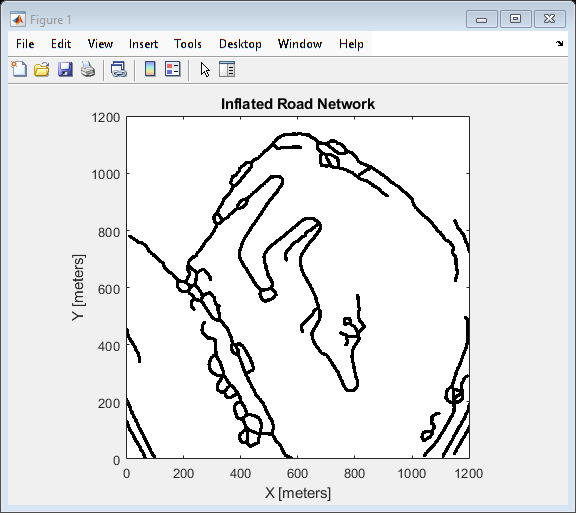

exampleHelperCreateBehaviorModelInputs
f = figure(1);
f.Visible = "on";

cla
binMap = binaryOccupancyMap(worldMat);
show(binMap);
title("MPC Following Reference Path")
hold on
axis equal
teb.ReferencePath = smoothedReferencePath;
curPose = teb.ReferencePath(1,:);
goalPos = smoothedReferencePath(300,1:2);
curVel = [0 0];
prevVel = [0 0];
curIdx = 1;
nPts = 50;
hGlobalPath = exampleHelperPlotLines(smoothedReferencePath,"k-");
hLocalPath = exampleHelperPlotLines(curPose,"r-");
hPivot = exampleHelperPlotLines(curPose,"mO");
hMPCRef = exampleHelperPose2Quiver(curPose,{'Color','b'},ArrowSize=0.1);
hMPCSoln = exampleHelperPose2Quiver(curPose,{'Color','g','LineWidth',2},ArrowSize=0.2);
fUpdateQuiv = @(f,poses)set(f,"XData",poses(:,1),"YData",poses(:,2),"UData",cos(poses(:,3)),"VData",sin(poses(:,3)));
legend({'Reference Path','Local Road','Pivot Points','MPC Reference Path','MPC Solution'})

% Reset MPC initial guess
simdata.InitialGuess = [];

### Simulate Path Following

To simulate following the road network with the MPC, follow these steps:

- Simulate until the current position is within 5 meters of the goal position on the path.

- Identify pivot points, and update the visualization for the chosen path segment.

- Generate and follow reference paths for each segment, using the MPC to calculate optimal control commands.

- Update the current pose and velocity based on the controller output, adjusting the path segment index as needed.

- Repeat the process for subsequent segments until you achieve the target proximity.

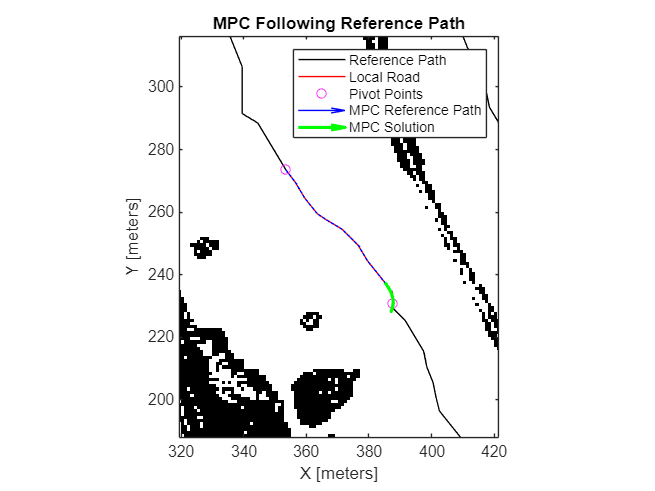

while vecnorm(curPose(1:2)-goalPos,2,2) > 5
    
    % Get next segment of N points from reference path
    initRefPath = smoothedReferencePath(curIdx:curIdx+nPts,:);
    [segmentList,pivotIdx,nSeg] = exampleHelperFindPivots(initRefPath);
    
    % Update visualization with pivot points and initial reference path
    set(hPivot,"XData",initRefPath(pivotIdx,1),"YData",initRefPath(pivotIdx,2));
    set(hLocalPath,"XData",initRefPath(:,1),"YData",initRefPath(:,2));
    exampleHelperPaddedZoom(initRefPath,2,"PaddingFactor",3)
    
    % Iterate through each path segment to follow the path
    for iSeg = 1:nSeg
        segment = segmentList(iSeg).States;
        refPath = exampleHelperEvenlyInterpSegment(segment,vNom,nlobjTracking.Ts);
        fUpdateQuiv(hMPCRef,refPath)
        while vecnorm(curPose(1:2)-segment(end,1:2),2,2) > 1
            % Generate reference states over prediction horizon
            simdata.StageParameter = exampleHelperGenerateMPCReferenceSegment(curPose,refPath,nlobjTracking.PredictionHorizon);
        
            % Step the MPC controller to get optimal velocity
            [curVel,simdata,info] = nlmpcmove(nlobjTracking,curPose,prevVel,simdata);
            fUpdateQuiv(hMPCSoln,info.Xopt)
            drawnow limitrate
    
            % Update pose and velocity states for next iteration
            curPose = info.Xopt(2,:);
            prevVel = curVel;

            if vecnorm(curPose(1:2)-goalPos,2,2) < 5
                break;
            end
        end
    end

    % Advance current index for next loop iteration without exceeding path length
    curIdx = min(curIdx+50,size(smoothedReferencePath,1));
end

Note that the MPC occasionally strays from the reference path, particularly around sharp turns. Although this deviation does not cause issues in this case, such deviations can cause issues if the turns are close to obstacles. To mitigate this, introduce the `controllerTEB` local planner from the Navigate Global Path Through Offroad Terrain Using Local Planner example as a bridge between the route planner and the MPC. The TEB planner generates paths that avoid collisions and respect the constraints of the kinematic model of the vehicle, making paths that are easier for the MPC to follow accurately.

## Follow Optimized TEB Paths with MPC

To incorporate the TEB controller into the MPC path following, first set up the TEB controller and maps. Then, during simulation, you can use the TEB controller to plan local optimal trajectories, generate velocity commands, and handle path-following issues such as deviating too much from the path. 

### Set Up Planners and Data

Load the data from the Create Route Planner for Offroad Navigation Using Digital Elevation Data and Create Terrain-Aware Global Planners for Offroad Navigation examples. The first MAT file contains the digital elevation map and path list representing the road network. The second MAT file contains a planned reference path through the road network, a smoothed version of the planned reference path, and parameters for the terrain-aware offramp planner.

load("OpenPitMinePart1Data.mat","dem","pathList")
load("OpenPitMinePart2Data.mat","originalReferencePath", ...
     "smoothedReferencePath","fixedTerrainAwareParams","tuneableTerrainAwareParams")

Create cost maps from the digital elevation map.

[costMap,maxSlope] = exampleHelperDem2mapLayers(dem,tuneableTerrainAwareParams.MaxAngle, ...
                                                    fixedTerrainAwareParams.Resolution);
obstacles = getLayer(costMap,"terrainObstacles");

Set the TEB controller parameters, and inflate the road network.

vehDims = exampleHelperVehicleGeometry(fixedTEBParams.Length,fixedTEBParams.Width,"collisionChecker");
collisionChecker = inflationCollisionChecker(vehDims,3);
exampleHelperInflateRoadNetwork(obstacles,pathList,collisionChecker.InflationRadius*1.5);

Compute the maximum distance traversable in an iteration of the TEB controller local planner, and create an egocentric local map based on that distance.

maxDistance = (tunableTEBParams.MaxVelocity(1)*tunableTEBParams.LookaheadTime/obstacles.Resolution);
localMap = binaryOccupancyMap(2*maxDistance,2*maxDistance,obstacles.Resolution);
localMap.GridOriginInLocal = -localMap.GridSize/(2*localMap.Resolution);

Create the TEB controller and update the parameters.

teb = controllerTEB(smoothedReferencePath,localMap);
teb.NumIteration           = fixedTEBParams.NumIteration;
teb.ReferenceDeltaTime     = fixedTEBParams.ReferenceDeltaTime;
teb.RobotInformation       = fixedTEBParams.RobotInformation;
teb.ObstacleSafetyMargin   = tunableTEBParams.ObstacleSafetyMargin;
teb.LookAheadTime          = tunableTEBParams.LookaheadTime; % In seconds
teb.CostWeights.Time       = tunableTEBParams.CostWeights.Time;
teb.CostWeights.Smoothness = tunableTEBParams.CostWeights.Smoothness;
teb.CostWeights.Obstacle   = tunableTEBParams.CostWeights.Obstacle;
teb.MinTurningRadius       = tunableTEBParams.MinTurningRadius;
teb.MaxVelocity            = tunableTEBParams.MaxVelocity;
teb.MaxAcceleration        = tunableTEBParams.MaxAcceleration;
teb.MaxReverseVelocity     = tunableTEBParams.MaxReverseVelocity;

### Simulate Path Following

Initialize the simulation parameters, such as the current pose and the goal position.

cla
teb.ReferencePath = smoothedReferencePath;
curPose = teb.ReferencePath(1,:);
goalPos = smoothedReferencePath(200,1:2);
curVel = [0 0];
prevVel = [0 0];
adjustedPath = 0;
curIdx = 1;

Center and show the map around the current pose of the haul truck.

move(localMap,curPose(1:2));
syncWith(localMap,obstacles);
show(localMap);
title("MPC Following TEB Planned Paths")
hold on
axis equal

Plot the smoothed reference path and initialize the plots for the TEB controller output path, the pivot points, the MPC reference path, and the output path from the MPC.

hGlobalPath = exampleHelperPlotLines(smoothedReferencePath,"k-");
hTEB = exampleHelperPlotLines(curPose,{'r-.',});
hPivot = exampleHelperPlotLines(curPose,'mO');
hMPCRef = exampleHelperPose2Quiver(curPose,{'Color','b'},ArrowSize=0.1);
hMPCSoln = exampleHelperPose2Quiver(curPose,{'Color','g','LineWidth',2},ArrowSize=0.2);
fUpdateQuiv = @(f,poses)set(f,"XData",poses(:,1),"YData",poses(:,2),"UData",cos(poses(:,3)),"VData",sin(poses(:,3)));
legend(["globalPath","tebSolution","pivotPoints","mpcRefPath","mpcSolution"])

Reset the initial guess of the MPC, and follow these steps to simulate MPC path-following supplemented with the TEB controller:

- Simulate until the current position of the haul truck is within 20 meters of the goal position.

- Use the TEB local planner to generate an optimal local trajectory, considering obstacles and the current state of the haul truck.

- Leverage the error flags and solution info capabilities of the TEB controller to determine if planned paths need adjustment, and adjust them as necessary. This ensures trajectory feasibility, addressing the issue of the haul truck straying from the path when using only the MPC.

- Extract an initial path segment from the TEB-generated path for MPC processing.

- Employ the MPC to compute optimal control commands for following the TEB-planned path, iteratively updating the pose and velocity states of the haul truck.

- Continue through the path segments until you achieve the target proximity to the goal.

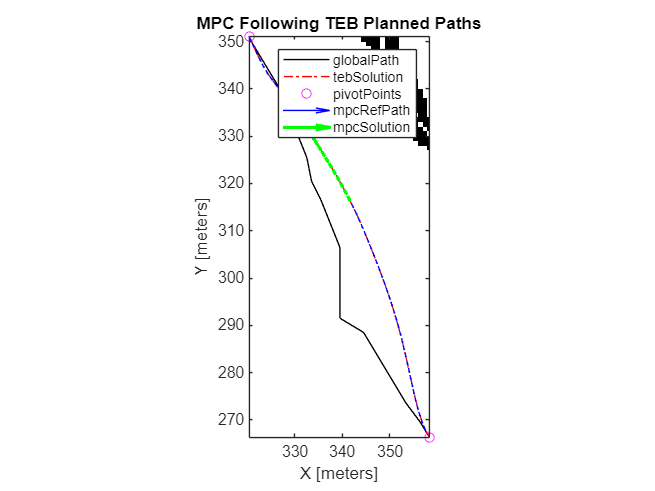

simdata.InitialGuess = [];
while vecnorm(curPose(1:2)-goalPos,2,2) > 20
    % Update the position of the local map, and synchronize with obstacles for TEB computation
    move(localMap,curPose(1:2),MoveType="absolute",SyncWith=obstacles);
    
    % Generate new velocity commands based on current pose using TEB
    [velcmds,tstamps,curPath,info] = teb(curPose,curVel);
    
    % Exit the loop if the goal position is reached according to TEB planner
    if info.HasReachedGoal
        break
    end

    % Transform the current pose into a rotation matrix for visualization
    hTEBPath2_2.Matrix(1:3,:) = [eul2rotm([0 0 curPose(3)],"XYZ") [curPose(1:2)'; 0]];

    % Analyze and adjust TEB path results (if needed) based on TEB error
    % codes and constraint violations
    [velcmds,tstamps,curPath,adjustedPath,needLocalReplan,needFreeSpaceReplan] = ...
        exampleHelperProcessTEBErrorCodes(teb,curPose,curVel,velcmds,tstamps, ...
                                          curPath,info,adjustedPath, ...
                                          teb.RobotInformation.Dimension(1), ...
                                          teb.RobotInformation.Dimension(2));

    % Skip to the next iteration if the TEB controller adjusted the path
    if adjustedPath
        continue
    end

    % Get next segment of N points from reference path
    initRefPath = curPath(1:max(2,size(curPath,1)),:);
    [segmentList,pivotIdx,nSeg] = exampleHelperFindPivots(initRefPath);
    simdata.InitialGuess = zeros(nlobjTracking.PredictionHorizon*7+3,1);

    % Update visualization with the TEB path and pivot points
    set(hTEB,"XData",initRefPath(:,1),"YData",initRefPath(:,2));
    set(hPivot,"XData",initRefPath(pivotIdx,1),"YData",initRefPath(pivotIdx,2));
    
    % Iterate through each path segment to follow the path
    for iSeg = 1:nSeg
        segment = segmentList(iSeg).States;
        [refPath,k] = exampleHelperEvenlyInterpSegment(segment,vNom,nlobjTracking.Ts,velcmds);
        fUpdateQuiv(hMPCRef,refPath);
        while vecnorm(curPose(1:2)-segment(end,1:2),2,2) > 0.4
            % Generate reference states over prediction horizon
            [mpcRef,idx] = exampleHelperGenerateMPCReferenceSegment(curPose,refPath,nlobjTracking.PredictionHorizon);
            simdata.StageParameter = mpcRef;
        
            % Step the MPC controller to get optimal velocity
            [curVel,simdata,info] = nlmpcmove(nlobjTracking,curPose,prevVel,simdata);
            fUpdateQuiv(hMPCSoln,info.Xopt);
    
            % Update pose and velocity states for next iteration
            curPose = info.Xopt(2,:);
            prevVel = curVel;
            show(localMap,FastUpdate=1);
            exampleHelperPaddedZoom(initRefPath,2,"PaddingFactor",1)
            drawnow

            if vecnorm(curPose(1:2)-goalPos,2,2) < 5
                break;
            end
        end
    end

    % Advance current index for next loop iteration without exceeding path length
    curIdx = min(curIdx+50,size(smoothedReferencePath,1));
end

## Conclusion

In this example, you developed an MPC for a three-DOF vehicle. You learned how to configure an `nlmpcMultistage` object for the three-DOF plant, and how to design state-update and cost functions to enable the haul truck to accurately track a reference path. You also learned how to design a reference signal such that the vehicle can optimally move along a reference path. Lastly, you saw how you can design an MPC to work with different upstream subsystems, such as a simple route planner or TEB controller.

Next, in the [Model and Control Autonomous Haul Truck](matlab:open('ModelAndControlAutonomousHaulTruck')) example, you will integrate all of the subsystems from this example using Simulink® and Stateflow®, creating an integrated model to serve as the planning stack for an autonomous haul truck in a pit mine.

*Copyright 2024 The MathWorks, Inc.*